clearvars

### INIT PARAM:

[x, q]=PAM_generator(4)

x =   -1.341640786499874  -0.447213595499958   0.447213595499958   1.341640786499874


q =    0.250000000000000   0.250000000000000   0.250000000000000   0.250000000000000


% Init param
SNR = -6; % dB

SNR = 10*log10(-6); % Aquest si que esta al DB
R = 0.55;
M = [2, 128, 4];
threshold = 2;

%TEST 1
[E, rho] = exponents(SNR, R, M, threshold)

error
Data not found in the server.
error
Data not found in the server.
error
Data not found in the server.


E = E(:,:,1) =

 -8.209741904004789 + 0.000000000000001i


E(:,:,2) =

-17.306300489524798 + 0.000000000000003i


E(:,:,3) =

-13.138591155808182 + 0.000000000000002i


rho = rho(:,:,1) =

     1


rho(:,:,2) =

     1


rho(:,:,3) =

     1


[~, sys] = memory;
memDisponible = sys.PhysicalMemory.Available;
disp(['Memoria disponible: ', num2str(memDisponible / 1e9), ' GB']);

Memoria disponible: 0.42711 GB


### PUJAR AL GOOGLE SHEET

## TEST M = 4

% TEST 4 --> Para el google sheet
% Modulacio - pel cas M = 8
M = 16;
% Quadratura - fixa
N = 20;
% SNR
SNR_values = 3;
% Rate
step = 1/100; %% 20 points
R_values = 0:step:1;
[Pe, rho, xx] = main(SNR_values, R_values, M, N);

% % Store data in google sheet
% for snr = 1:length(SNR_values)
%     for r = 1:length(R_values)
%         %[E, rho] = main(SNR_values(snr), R_values(r), M , N);
%         data.SNR = SNR_values(snr);
%         if r == length(R_values)
%             data.R = 2;
%         else
%             data.R = R_values(r);
%         end
%     
%         data.N = N;
%         data.E = Pe(snr, r, 1, 1);
%         data.RHO = rho(snr, r, 1, 1);
%         
%         url = 'https://script.google.com/macros/s/AKfycbwHyxKu3ePMwZavBo0S-DV-Cb91EvFihTSAdG2OriIcunVZGTQf2H5y669iOYg-PXir/exec';
%         options = weboptions('ContentType', 'json', 'RequestMethod', 'post', 'Timeout', 10, 'ArrayFormat', 'json');
% 
%         try
%             response = webwrite(url, data, options);
%             disp("Respuesta del servidor:");
%             % Display the response from the web app
%             disp(response);
%         catch ME
%             %disp("Error:");
%             %disp(ME.message);
%         end
%     end
% end

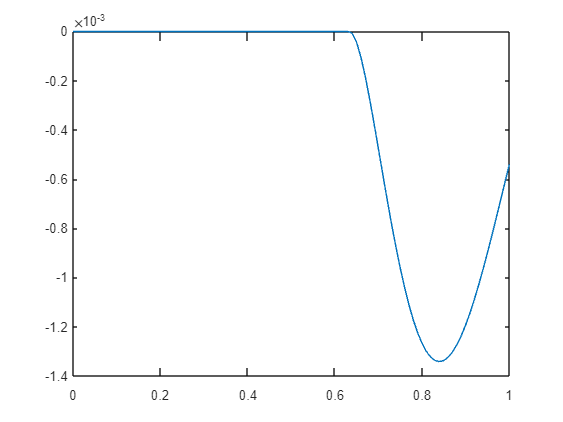

% plot(xx)
% hold on
clf
plot(R_values,Pe-xx)

% hold on
% plot(R_values,xx)


clearvars
clf
N = 20;
M = 6;
[x, q] = PAM_generator(M);
[z, w] = GaussHermite_Locations_Weights(N);

clip = 1:100;

for SNR_dB = -20:5:20
    [Q, PI_, G] = matrix_generator(N, q, x, w, z, SNR_dB);
    y = zeros(1, length(clip));

    for i = 1:length(clip)
        Gclip = max(G, exp(-clip(i))); % Clipping per evitar NaN
        y(i) = abs(E0_matrix(Q, PI_, Gclip, 1)-E0_matrix(Q, PI_, G, 1));
        
    end
    semilogy(clip, y)
    hold on
      
end

Not enough input arguments.

Error in matrix_generator (line 8)
    G = max(G, exp(-clip)); % Clipping per evitar NaN

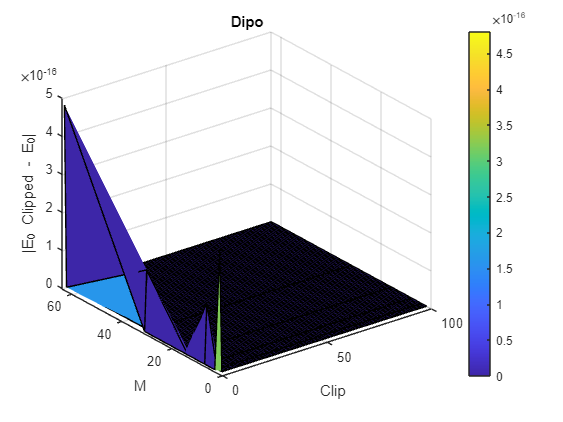

clearvars
clf
M = 6; 
N = 20;
M_values = 2.^(1:M); 
clip = 1:100;
SNR_dB_values = -20:5:20; 

[X, Y] = meshgrid(clip, M_values); 
Z = zeros(length(M_values), length(clip));

SNR_dB = 0;

for m_idx = 1:length(M_values)
    M = M_values(m_idx);
    [x, q] = PAM_generator(M);
    [z, w] = GaussHermite_Locations_Weights(N);
    
    [Q, PI_, G] = matrix_generator(N, q, x, w, z, SNR_dB);

    for i = 1:length(clip)
        Gclip = max(G, exp(-clip(i))); % Clipping para evitar NaN
        Z(m_idx, i) = abs(E0_matrix(Q, PI_, Gclip, 1) - E0_matrix(Q, PI_, G, 1));
    end
end

% Graficamos en 3D
figure
surf(X, Y, Z)
xlabel('Clip')
ylabel('M')
zlabel('|E_0 Clipped - E_0|')
title('Dipo')
colorbar
grid on